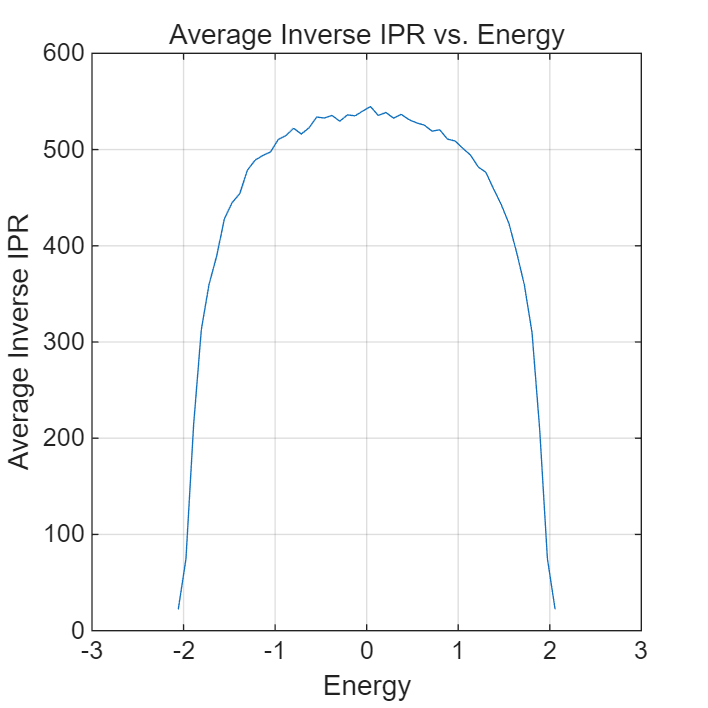

% diagonalization_anderson_model_1d(1000, 0, 0)
diagonalization_anderson_model_1d(1000, 1,1.5)

function diagonalization_anderson_model_1d(L, W, energy)
% 用法: diagonalization_anderson_model_1d(L, W, energy)
% 例如: diagonalization_anderson_model_1d(100, 2, 0)

% 生成随机势
disorder = W * (rand(L,1) - 0.5);

% 构造哈密顿量
H = diag(ones(L-1,1),-1) + diag(ones(L-1,1),1) + diag(disorder);

% 对角化
[eigenstates, energy_levels] = eig(H);
energy_levels = diag(energy_levels);

% 排序
[energy_levels, idx] = sort(energy_levels, 'ascend');
eigenstates = eigenstates(:, idx);

% 输出能谱
figure
plot(energy_levels)

figure
% 找到最接近energy的本征态
[~, i] = min(abs(energy_levels - energy));
plot(eigenstates(:, i))
% yscale log
end




compute_IPR_anderson_model_1D(1000, 0.2, 50, 50)



function compute_IPR_anderson_model_1D(L, W, nr, nbin)
% 用法: compute_IPR_anderson_model_1D(L, W, nr, nsteps)
% 例如: compute_IPR_anderson_model_1D(100, 2, 100, 200)
% L: system size
% W: disorder strength
% nh: number of disorder realizations
% nsteps: number of bins in the histogram of average(1/IPR) vs. energy
energy_min = -2.0 - 0.5*W;
energy_max =  2.0 + 0.5*W;
IPR = zeros(L, nr);
energy_levels = zeros(L, nr);

for ir = 1:nr
    % 生成哈密顿量
    disorder = W * (rand(L,1) - 0.5);
    % 构造哈密顿量
    H = diag(ones(L-1,1),-1) + diag(ones(L-1,1),1) + diag(disorder);
    % 对角化
    [eigenstates, D] = eig(H);
    energies = diag(D);
    % 计算IPR
    ipr = sum(eigenstates.^4, 1);
    energy_levels(:, ir) = energies;
    IPR(:, ir) = ipr;
end

% 排序
[energy_levels, idx] = sort(energy_levels(:), 'ascend');
IPR = IPR(idx);

[bin_idx, bin_Edge] = discretize(energy_levels, linspace(energy_min, energy_max, nbin+1));
bin_center = (bin_Edge(1:end-1) + bin_Edge(2:end))/2;
% 计算每个bin的平均1/IPR
inv_IPR = 1 ./ IPR;
inv_IPR_bin = accumarray(bin_idx, inv_IPR, [nbin, 1], @mean, NaN);
plot(bin_center,inv_IPR_bin)
% 


% 绘制 IPR 随能量的散点图

xlabel('Energy');
ylabel('Average Inverse IPR');
title('Average Inverse IPR vs. Energy');
grid on;
end